clear

ParentDir = "F:\YuLab\Work\GPS\Video";
TaskDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(TaskDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(TaskDir, TrajGroupClassFile.name));


save_name = "DistDTWMatrix_" + obj.ANM + "_" + obj.Task + "_z.mat";
save_path = fullfile(TaskDir, save_name);

if exist(save_path, 'file')

    load(save_path);

else

    D_dtw = cell(1, length(obj.Ports));

    for j = 1:2

        disp(j)

        these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
        these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
        these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

        M = cell(length([these_trials_control; these_trials_chemo]), 1);
        for t = 1:length(these_trials_control)
            M{t} = obj.AngleHeadMatIn(these_trials_control(t), 100:100+floor(1000*obj.HD(these_trials_control(t))));
        end
        for t = 1:length(these_trials_chemo)
            M{t+length(these_trials_control)} = obj.AngleHeadMatIn(these_trials_chemo(t), 100:100+floor(1000*obj.HD(these_trials_chemo(t))));
        end

        D_dtw{j} = zeros(length(M), length(M));
        for m = 1:length(M)
            for n = m+1:length(M)
                D_dtw{j}(m, n) = dtw(M{m}, M{n});
            end
        end
        % 填充对称位置
        D_dtw{j} = D_dtw{j} + D_dtw{j}';
        D_dtw{j} = normalize(D_dtw{j}(:), 'range');
        D_dtw{j} = reshape(D_dtw{j}, length(M), length(M));
    end

    save(save_path, "D_dtw");
end

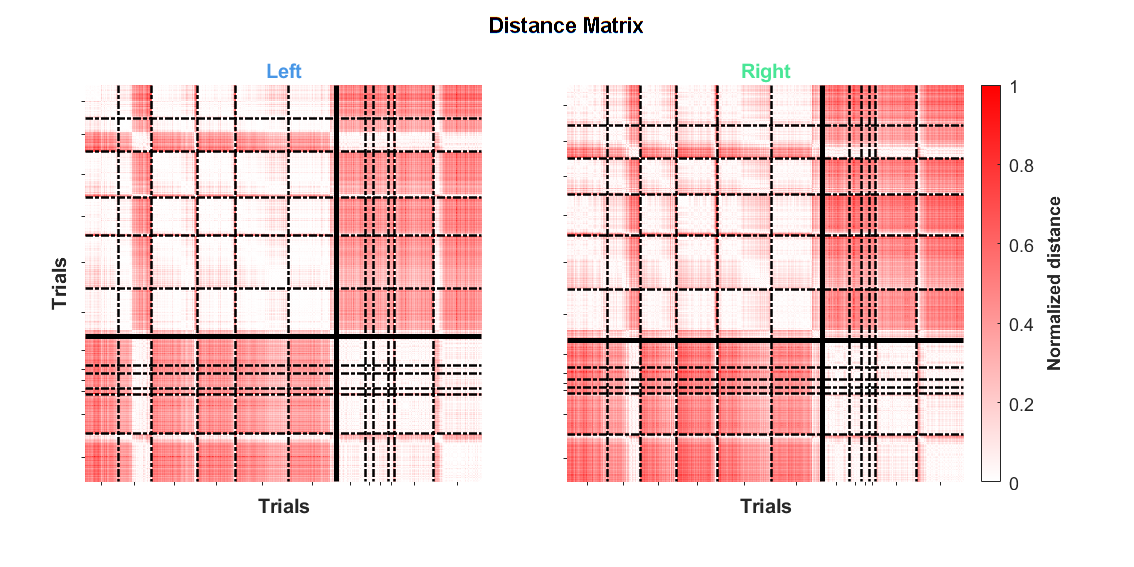

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

fig_rsm = figure(51); clf(51);
set(fig_rsm, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_rsm, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "Distance Matrix", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    ax_rsm = axes;
    set(ax_rsm, 'Units', 'Centimeters', 'Position', [1.5+8.5*(j-1) 1.5 7 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);

    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    sessions_control = obj.TrialInfo.Session(these_trials_control);
    sessions_control_id = unique(sessions_control);
    num_trials_control = zeros(length(sessions_control_id), 1);
    for k = 1:length(sessions_control_id)
        num_trials_control(k) = sum(sessions_control==sessions_control_id(k));
    end

    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    sessions_chemo = obj.TrialInfo.Session(these_trials_chemo);
    sessions_chemo_id = unique(sessions_chemo);
    num_trials_chemo = zeros(length(sessions_chemo_id), 1);
    for k = 1:length(sessions_chemo_id)
        num_trials_chemo(k) = sum(sessions_chemo==sessions_chemo_id(k));
    end

    session_seps = cumsum([num_trials_control; num_trials_chemo]) + 0.5;

    colormap(mycolormap);
    imagesc(D_dtw{j}); clim([0 1]);

    xline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
    yline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

    xline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);
    yline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'k', 'Alpha', 1);

    xlim([.5 length(these_trials)+.5]);
    ylim([.5 length(these_trials)+.5]);

    xticks(session_seps - [num_trials_control; num_trials_chemo] / 2); xticklabels([]);
    yticks(session_seps - [num_trials_control; num_trials_chemo] / 2); yticklabels([]);

    if j == 1
        ax_rsm.YLabel.String = "Trials";
        ax_rsm.YLabel.FontWeight = "Bold";
    end
    ax_rsm.XLabel.String = "Trials";
    ax_rsm.XLabel.FontWeight = "Bold";

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_rsm, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

end

ax_cb = axes;
set(ax_cb, 'Units', 'Centimeters', 'Position', [13.5 1.5 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none');
cb = colorbar;
clim(ax_cb, [0 1]);
cb.FontSize = 9;
cb.Label.String = "Normalized distance";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';

save_name = "DistDTWMatrix_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_rsm, save_path);

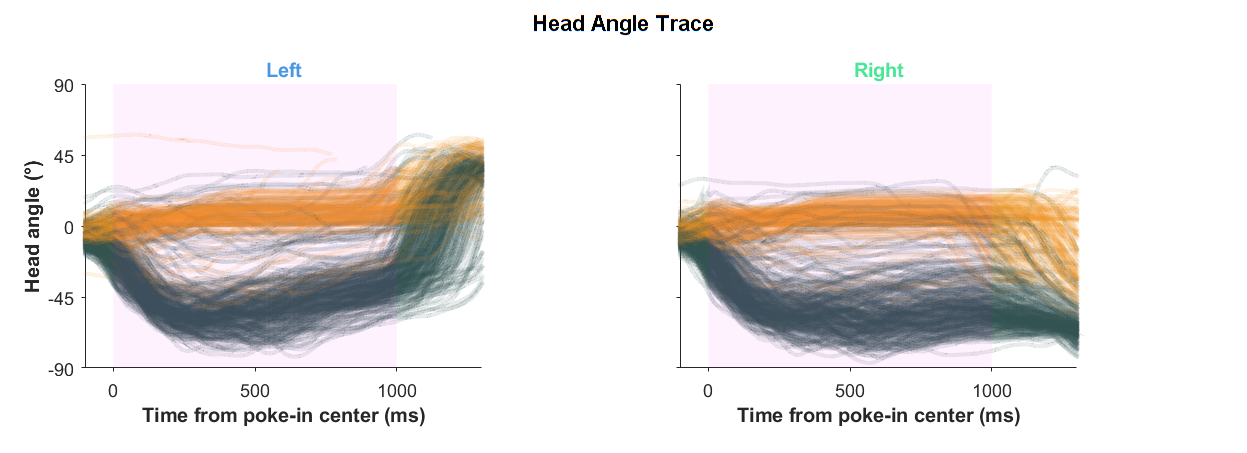

fig_trace = figure(52); clf(52);
set(fig_trace, 'Units', 'Centimeters', 'Position', [1 1 22 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_trace, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "Head Angle Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

plot_height = 5;
plot_width  = [9 14 19] / 2;

for j = 1:2

    ax_trace = axes;
    set(ax_trace, 'Units', 'Centimeters', 'Position', [1.5+10.5*(j-1) 1.5 2+5*obj.TaskFP plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    fp_begin = 0;
    fp_end   = 1000*obj.TaskFP;

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials = these_trials(randperm(length(these_trials)));

    for k = 1:length(these_trials)
        switch obj.TrialInfo.Label(these_trials(k))
            case "Chemo"
                color_this = GPSColor.Treat;
            case "Control"
                color_this = GPSColor.Control;
        end
        patch(ax_trace, 'XData', [obj.TimePointsIn(1:100+1000*obj.TaskFP+300) nan], 'YData', [obj.AngleHeadMatIn(these_trials(k), (1:100+1000*obj.TaskFP+300)) nan], 'EdgeColor', color_this, 'EdgeAlpha', 0.1, 'LineWidth', 2)
    end

    %     plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.TaskFP+300), mean(obj.AngleHeadMatIn(these_trials_control, 1:100+1000*obj.TaskFP+300)), ...
    %         'Color', GPSColor.Control, 'LineWidth', 4)
    %
    %     plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.TaskFP+300), mean(obj.AngleHeadMatIn(these_trials_chemo, 1:100+1000*obj.TaskFP+300)), ...
    %         'Color', GPSColor.Treat, 'LineWidth', 4)

    patch(ax_trace, 'XData', [fp_begin fp_end fp_end fp_begin], 'YData', [-90 -90 90 90], 'FaceColor', 'm', 'FaceAlpha', 0.05, 'EdgeColor', 'none')

    set(ax_trace, 'XLim', [-100 1000*obj.TaskFP+300], 'YLim', [-90 90], 'XTick', 0:500:1500, 'YTick', -90:45:90);

    ax_trace.XLabel.String = "Time from poke-in center (ms)";
    ax_trace.XLabel.FontWeight = "bold";

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_trace, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    if j == 1
        ax_trace.YLabel.String = "Head angle (°)";
        ax_trace.YLabel.FontWeight = "bold";
    end
    if j == 2
        ax_trace.YTickLabel = [];
    end

end

save_name = "HeadAngleTrace_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_trace, save_path);

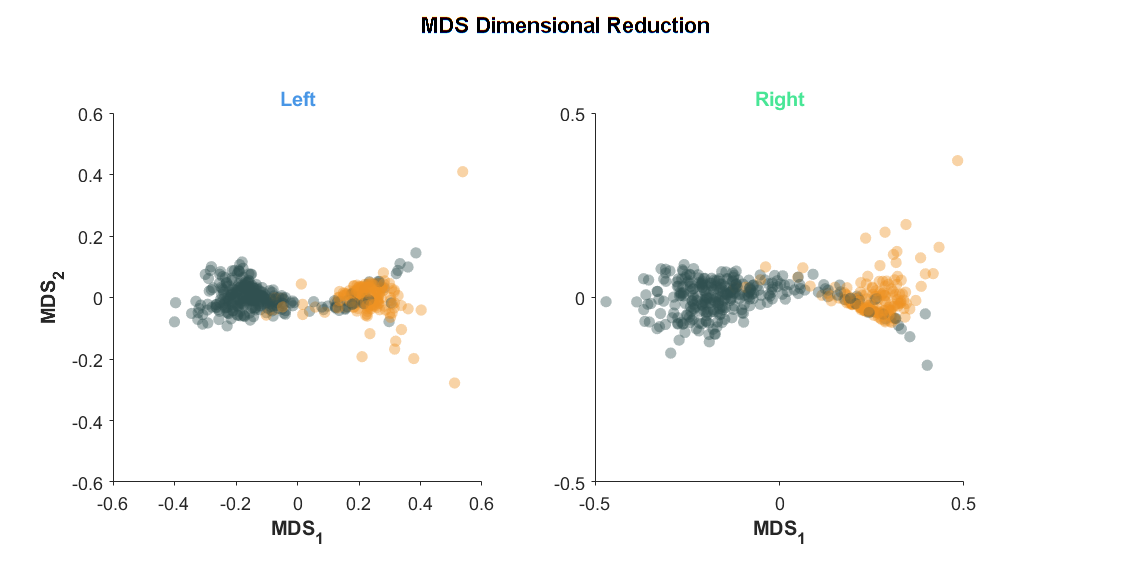

fig_mds = figure(54); clf(54);
set(fig_mds, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Dimensional Reduction", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

MDS_score = cell(1, length(obj.Ports));
MDS_cost  = cell(1, length(obj.Ports));

for j = 1:2

    [MDS_score{j}, MDS_cost{j}] = cmdscale(D_dtw{j});

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));
    this_color = [repmat(GPSColor.Control, length(these_trials_control), 1); repmat(GPSColor.Treat, length(these_trials_chemo), 1)];
    id_shuffle = randperm(length(these_trials));

    hd = obj.HD([these_trials_control; these_trials_chemo]);

    ax_mds = axes;
    set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    scatter(ax_mds, MDS_score{j}(id_shuffle,1), MDS_score{j}(id_shuffle,2), 32, this_color(id_shuffle, :), 'filled', 'MarkerFaceAlpha', 0.4, 'MarkerEdgeColor', 'none');

    if j == 1
        ax_mds.YLabel.String = "MDS_2";
        ax_mds.YLabel.FontWeight = "Bold";
    end
    ax_mds.XLabel.String = "MDS_1";
    ax_mds.XLabel.FontWeight = "Bold";

    ax_mds.YLim = ax_mds.XLim;

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');
end

save_name = "MDS_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mds, save_path);

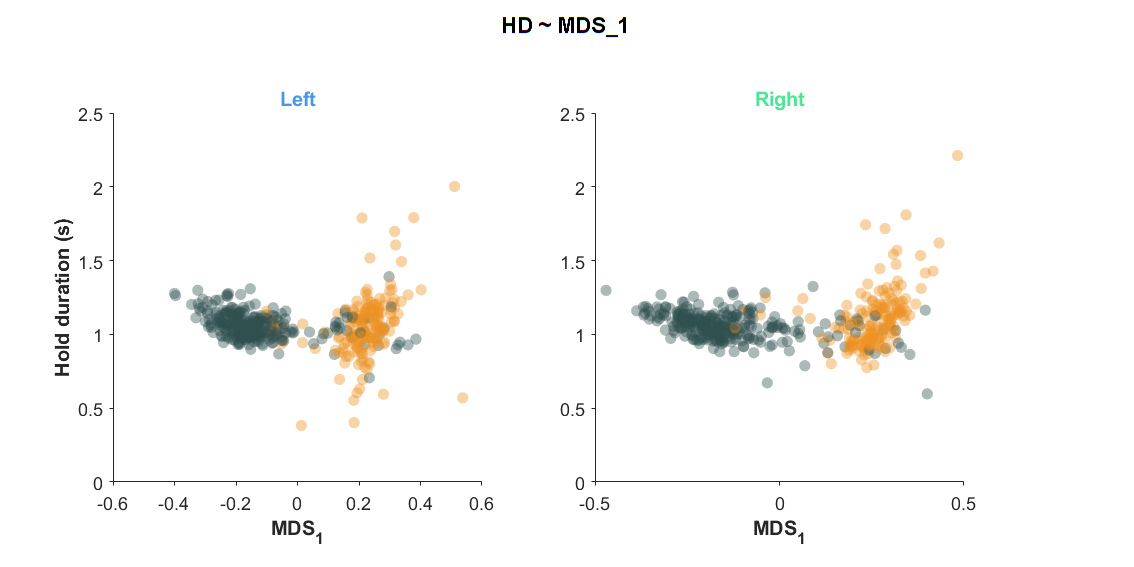

fig_hd_mds = figure(61); clf(61);
set(fig_hd_mds, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_hd_mds, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "HD ~ MDS_1", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2
    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));
    this_color = [repmat(GPSColor.Control, length(these_trials_control), 1); repmat(GPSColor.Treat, length(these_trials_chemo), 1)];
    id_shuffle = randperm(length(these_trials));

    hd = obj.HD([these_trials_control; these_trials_chemo]);

    ax_mds = axes;
    set(ax_mds, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    scatter(ax_mds, MDS_score{j}(id_shuffle,1),hd(id_shuffle), 32, this_color(id_shuffle, :), 'filled', 'MarkerFaceAlpha', 0.4, 'MarkerEdgeColor', 'none');

    if j == 1
        ax_mds.YLabel.String = "Hold duration (s)";
        ax_mds.YLabel.FontWeight = "Bold";
    end
    ax_mds.XLabel.String = "MDS_1";
    ax_mds.XLabel.FontWeight = "Bold";

    ax_mds.YLim = [0 2.5];

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

end

save_name = "HD_MDS_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_hd_mds, save_path);

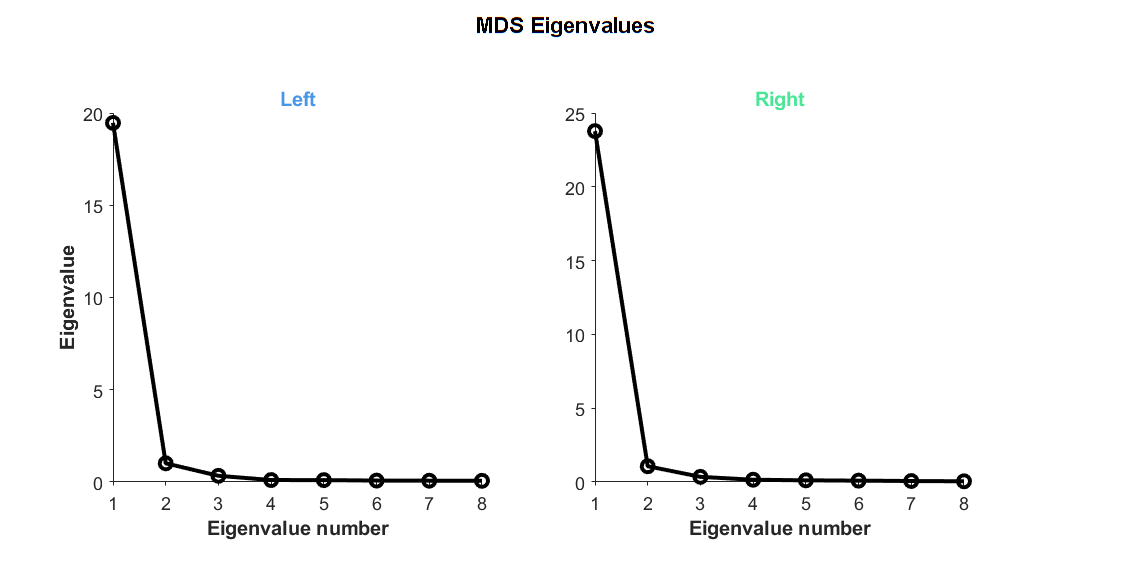

fig_mds_cost = figure(55); clf(55);
set(fig_mds_cost, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_mds_cost, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "MDS Eigenvalues", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for j = 1:2

    ax_mds_cost = axes;
    set(ax_mds_cost, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    plot(ax_mds_cost, 1:8, MDS_cost{j}(1:8), '-ok', 'LineWidth', 2);

    if j == 1
        ax_mds_cost.YLabel.String = "Eigenvalue";
        ax_mds_cost.YLabel.FontWeight = "Bold";
    end

    ax_mds_cost.XLabel.String = "Eigenvalue number";
    ax_mds_cost.XLabel.FontWeight = "Bold";

    ax_mds_cost.XLim = [1 8];

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds_cost, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

end

save_name = "MDS_Eigenvalue_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mds_cost, save_path);

Mdl_cv = cell(1, length(obj.Ports));
Acc_cv = cell(1, length(obj.Ports));

MotorType = nan(length(obj.HD), 1);
for j = 1:2

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));

    y = [zeros(length(id_control), 1); ones(length(id_chemo), 1)];
    x = MDS_score{j}(:,1:2);

    Mdl = fitcdiscr(x, y);
    y_fit = predict(Mdl, x);
    MotorType([these_trials_control; these_trials_chemo]) = y_fit;

    cvp = cvpartition(y,'KFold',10);

    Mdl_cv{j} = fitcdiscr(x, y, "CrossVal", "on", "CVPartition", cvp);

    Acc_cv{j} = 1-kfoldLoss(Mdl_cv{j}, "Mode", "individual");

end

Acc_mean = cellfun(@(x) mean(x), Acc_cv);
Acc_std = cellfun(@(x) std(x), Acc_cv);
Acc_sem = Acc_std ./ sqrt(10);


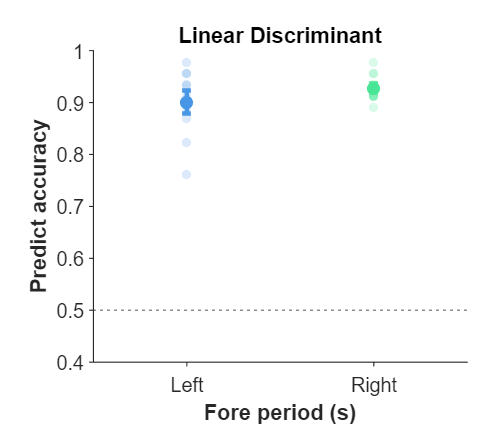


fig_mdl = figure(56); clf(56);
set(fig_mdl, 'Units', 'Centimeters', 'Position', [1 1 8 7], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_mdl = axes;
set(ax_mdl, 'Units', 'Centimeters', 'Position', [1.5 1.2 6 5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

yline(ax_mdl, .5, 'LineStyle', ':');

scatter(ax_mdl, 1, Acc_cv{1}, 18, 'Marker', 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', 0.2);
scatter(ax_mdl, 2, Acc_cv{2}, 18, 'Marker', 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', 0.2);

errorbar(ax_mdl, 1, Acc_mean(1), Acc_sem(1), 'Color', GPSColor.PortL, 'LineWidth', 2, 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor', GPSColor.PortL, 'MarkerEdgeColor', 'none', 'MarkerSize', 6, 'CapSize', 4)
errorbar(ax_mdl, 2, Acc_mean(2), Acc_sem(2), 'Color', GPSColor.PortR, 'LineWidth', 2, 'LineStyle', 'none', 'Marker', 'o', 'MarkerFaceColor', GPSColor.PortR, 'MarkerEdgeColor', 'none', 'MarkerSize', 6, 'CapSize', 4)

xlim(ax_mdl, [.5 2.5]); ylim([0.4 1]);
xticks(ax_mdl, [1 2]);
xticklabels(ax_mdl, {'Left', 'Right'});

xlabel(ax_mdl, 'Fore period (s)', 'FontWeight', 'bold');
ylabel(ax_mdl, 'Predict accuracy', 'FontWeight', 'bold');

title(ax_mdl, 'Linear Discriminant', 'FontWeight', 'bold');
save_name = "Classifier_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mdl, save_path);

Mdl = fitcdiscr(x, y);
y_fit = predict(Mdl, x);

correct_reject = sum(y==0 & y_fit==0) / sum(y==0)

correct_reject = 0.9078

hit = sum(y==1 & y_fit==1) / sum(y==1)

hit = 0.9630

false_alarm = sum(y==0 & y_fit==1) / sum(y==0)

false_alarm = 0.0922

miss = sum(y==1 & y_fit==0) / sum(y==1)

miss = 0.0370

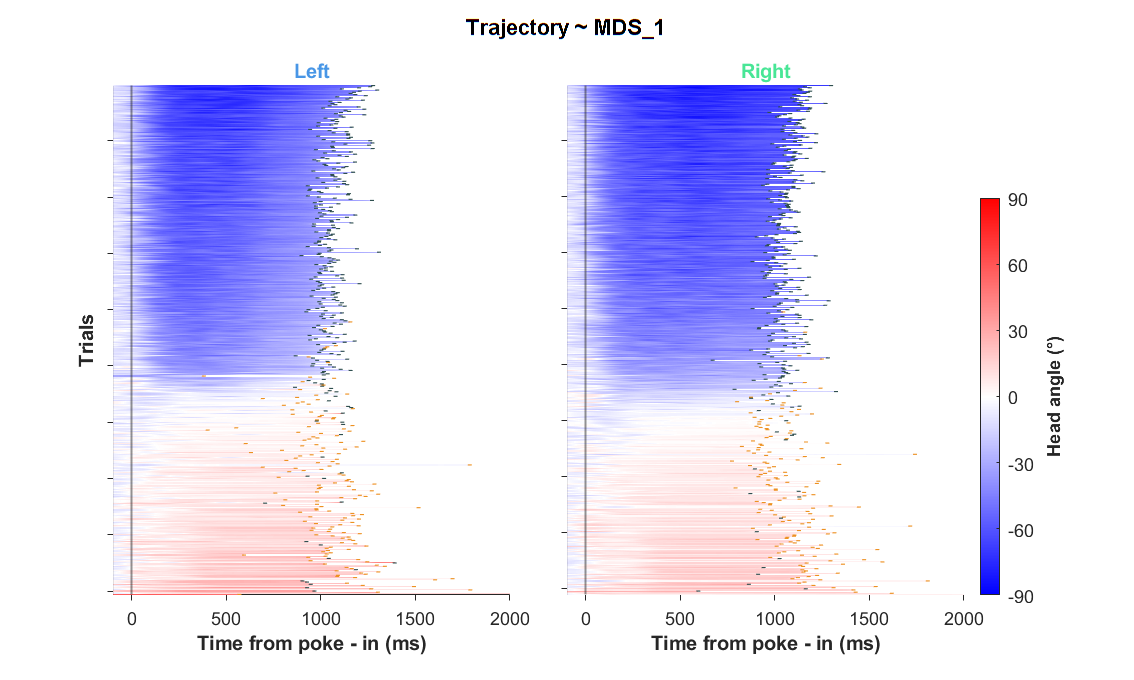

fig_mds_traj = figure(62); clf(62);
set(fig_mds_traj, 'Units', 'Centimeters', 'Position', [1 1 20 12], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_mds_traj, 'units', 'normalized', 'position', [0.2 0.92 0.6 0.06],...
    'string', "Trajectory ~ MDS_1", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

mycolormap = customcolormap([0 0.5 1], [1 0 0; 1 1 1; 0 0 1]);

for j = 1:2

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

    traj_mat = obj.AngleHeadMatIn([these_trials_control; these_trials_chemo], :);

    trial_id = [these_trials_control; these_trials_chemo];

    for i = 1:length(trial_id)
        traj_mat(i, floor(100+1000*obj.HD(trial_id(i))):end ) = nan;
    end

    [~, id_sort] = sort(MDS_score{j}(:, 1));

    ax_mds_traj = axes;
    set(ax_mds_traj, 'Units', 'Centimeters', 'Position', [2+8*(j-1) 1.5 7 9], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

    colormap(ax_mds_traj, mycolormap);

    xline(ax_mds_traj, 100, 'LineWidth', 1, 'Alpha', 0.5)
    imagesc(ax_mds_traj, traj_mat(id_sort, :), "AlphaData", ~isnan(traj_mat(id_sort, :)));
    for i = 1:length(trial_id)
        this_trial = trial_id(id_sort(i));
        switch obj.TrialInfo.Label(this_trial)
            case "Chemo"
                this_color = GPSColor.Treat;
            case "Control"
                this_color = GPSColor.Control;
        end

        out_time = find(~isnan(traj_mat(id_sort(i), :)), 1, 'last');
        plot(ax_mds_traj, [out_time out_time], i+[-.5 .5], 'LineWidth', 2, 'Color', this_color);
    end

    ylim(ax_mds_traj, .5 + [0 length(trial_id)]);
    xlim(ax_mds_traj, [0 100+2000])
    xticks(ax_mds_traj, 100:500:3100);
    xticklabels(ax_mds_traj, {'0', '500', '1000', '1500', '2000', '2500', '3000'});
    xlabel(ax_mds_traj, 'Time from poke - in (ms)', 'FontWeight', 'bold');
    if j==1
        ylabel(ax_mds_traj, 'Trials', 'FontWeight', 'bold');
    end
    yticklabels(ax_mds_traj, [])
    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_mds_traj, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');

    clim(ax_mds_traj, [-90 90]);

end
ax_cb_2 = axes;
set(ax_cb_2, 'Units', 'Centimeters', 'Position', [13.5 1.5 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none', 'Colormap', mycolormap);
cb = colorbar;
clim(ax_cb_2, [-90 90]);
cb.Ticks = -90:30:90;
cb.FontSize = 9;
cb.Label.String = "Head angle (°)";
cb.Label.FontSize = 9;
cb.Label.FontWeight = 'bold';

save_name = "MDS_Traj_" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_mds_traj, save_path);

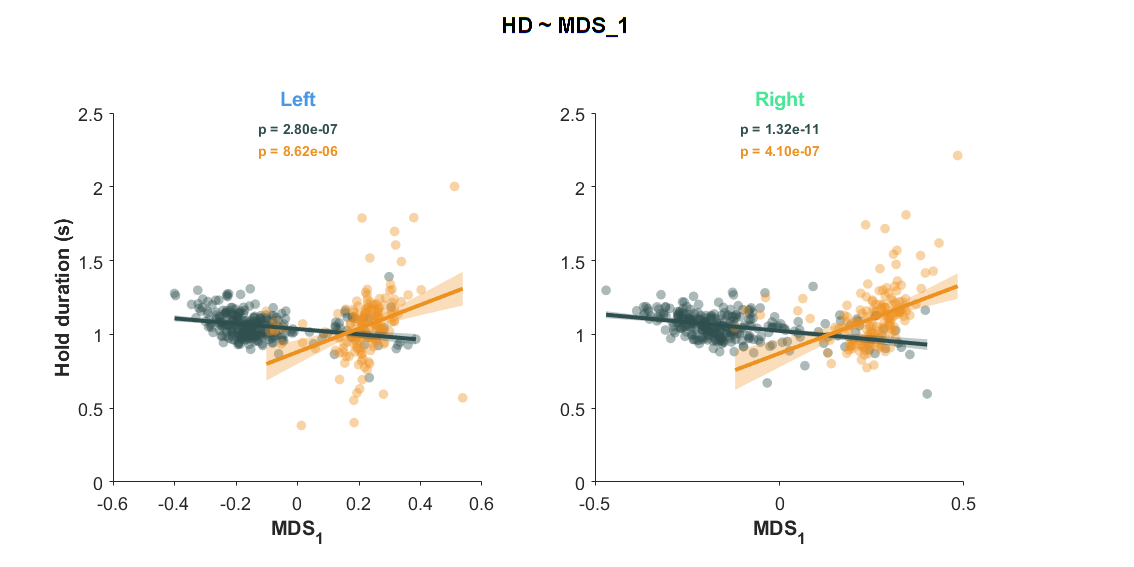


fig_hd_mds_fit = figure(61); clf(61);
set(fig_hd_mds_fit, 'Units', 'Centimeters', 'Position', [1 1 20 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_hd_mds_fit, 'units', 'normalized', 'position', [0.2 0.9 0.6 0.08],...
    'string', "HD ~ MDS_1", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');
% j = 1;
for j = 1:2

    ax_hd_mds_fit = axes;
    set(ax_hd_mds_fit, 'Units', 'Centimeters', 'Position', [2+8.5*(j-1) 1.5 6.5 6.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    these_trials = find(obj.TrialInfo.PortCorrect==obj.Ports(j) & obj.TrialInfo.Cued==0 & obj.TrialInfo.Stage==1 & obj.TrialInfo.zi>0.5);
    these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
    these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
    id_control = 1:length(these_trials_control);
    id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));
    this_color = [repmat(GPSColor.Control, length(these_trials_control), 1); repmat(GPSColor.Treat, length(these_trials_chemo), 1)];
    id_shuffle = randperm(length(these_trials));

    hd = obj.HD([these_trials_control; these_trials_chemo])';
    mds_1 = MDS_score{j}(:,1);
    treat = [zeros(length(these_trials_control), 1); ones(length(these_trials_chemo), 1)];

    D = table(hd, mds_1, treat);
    D = sortrows(D, "mds_1");
    D_control = D(D.treat==0, :);
    D_chemo = D(D.treat==1, :);

    model_spec_inter = "hd ~ mds_1 + treat + mds_1*treat";
    model_spec_simple = "hd ~ mds_1";

    mdl_inter = fitlm(D, model_spec_inter);
    mdl_control = fitlm(D_control, model_spec_simple);
    mdl_chemo = fitlm(D_chemo, model_spec_simple);

    [hd_pred_control, ci_pred_control] = predict(mdl_control, D_control);
    p_control = mdl_control.Coefficients.pValue(2);

    [hd_pred_chemo, ci_pred_chemo] = predict(mdl_chemo, D_chemo);
    p_chemo = mdl_chemo.Coefficients.pValue(2);

    % Scatter
    scatter(ax_hd_mds_fit, D_control.mds_1, D_control.hd, ...
        24, GPSColor.Control, "filled", "o", "MarkerFaceAlpha", 0.4, "MarkerEdgeAlpha", 0.4);
    scatter(ax_hd_mds_fit, D_chemo.mds_1, D_chemo.hd, ...
        24, GPSColor.Treat  , "filled", "o", "MarkerFaceAlpha", 0.4, "MarkerEdgeAlpha", 0.4);
    fill(ax_hd_mds_fit, [D_control.mds_1; flip(D_control.mds_1)], [ci_pred_control(:, 1); flip(ci_pred_control(:, 2))], GPSColor.Control, "FaceAlpha", 0.3, "EdgeColor", "none");
    fill(ax_hd_mds_fit, [D_chemo.mds_1; flip(D_chemo.mds_1)], [ci_pred_chemo(:, 1); flip(ci_pred_chemo(:, 2))], GPSColor.Treat, "FaceAlpha", 0.3, "EdgeColor", "none");
    plot(ax_hd_mds_fit, D_control.mds_1, hd_pred_control, "Color", GPSColor.Control, "LineWidth", 2)
    plot(ax_hd_mds_fit, D_chemo.mds_1, hd_pred_chemo, "Color", GPSColor.Treat, "LineWidth", 2)

    text(ax_hd_mds_fit, 0, 2.4, sprintf("p = %.2e", p_control), ...
        "Color", GPSColor.Control, "HorizontalAlignment", "center", "FontSize", 7, "FontWeight", "bold")
    text(ax_hd_mds_fit, 0, 2.25, sprintf("p = %.2e", p_chemo), ...
        "Color", GPSColor.Treat, "HorizontalAlignment", "center", "FontSize", 7, "FontWeight", "bold")

    if j == 1
        ax_hd_mds_fit.YLabel.String = "Hold duration (s)";
        ax_hd_mds_fit.YLabel.FontWeight = "Bold";
    end
    ax_hd_mds_fit.XLabel.String = "MDS_1";
    ax_hd_mds_fit.XLabel.FontWeight = "Bold";

    ax_hd_mds_fit.YLim = [0 2.5];

    switch j
        case 1
            title_text = "Left";
        case 2
            title_text = "Right";
    end
    title(ax_hd_mds_fit, title_text, 'Color', GPSColor.("Port"+obj.Ports(j)), 'FontWeight', 'bold');
end

save_name = "HD_MDS_fit" + obj.ANM + "_" + obj.Task + "_z.jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_hd_mds_fit, save_path);

[~, pca_score, ~, ~, expained] = pca(D_dtw{1});

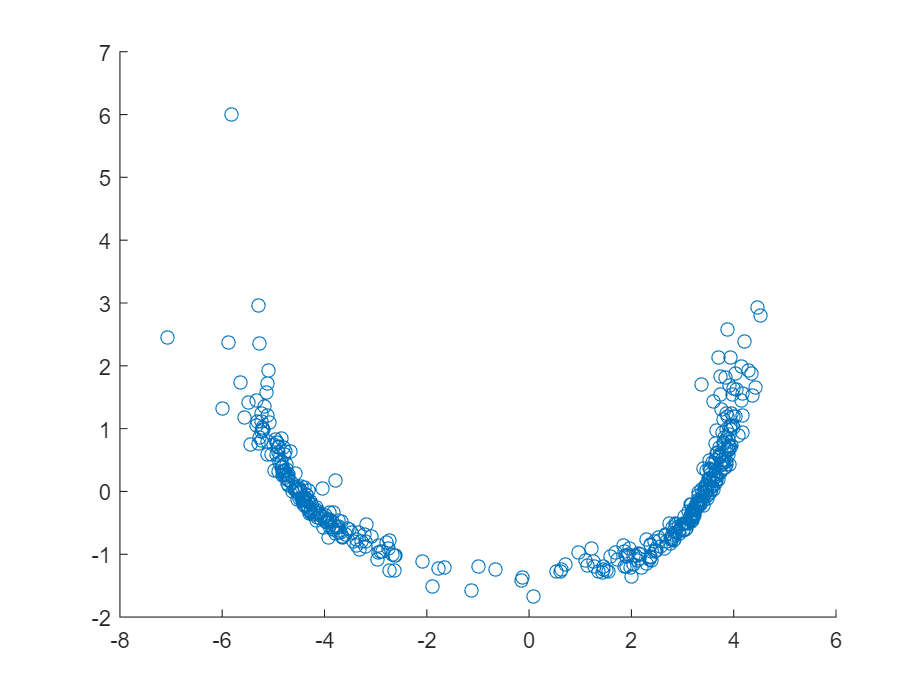

figure();
scatter(pca_score(:,1), pca_score(:,2))

tsne_score = tsne_d(D_dtw{2}, [], 2, 20 );

Mean value of sigma: 0.0085332
Minimum value of sigma: 0.0029138
Maximum value of sigma: 0.053138


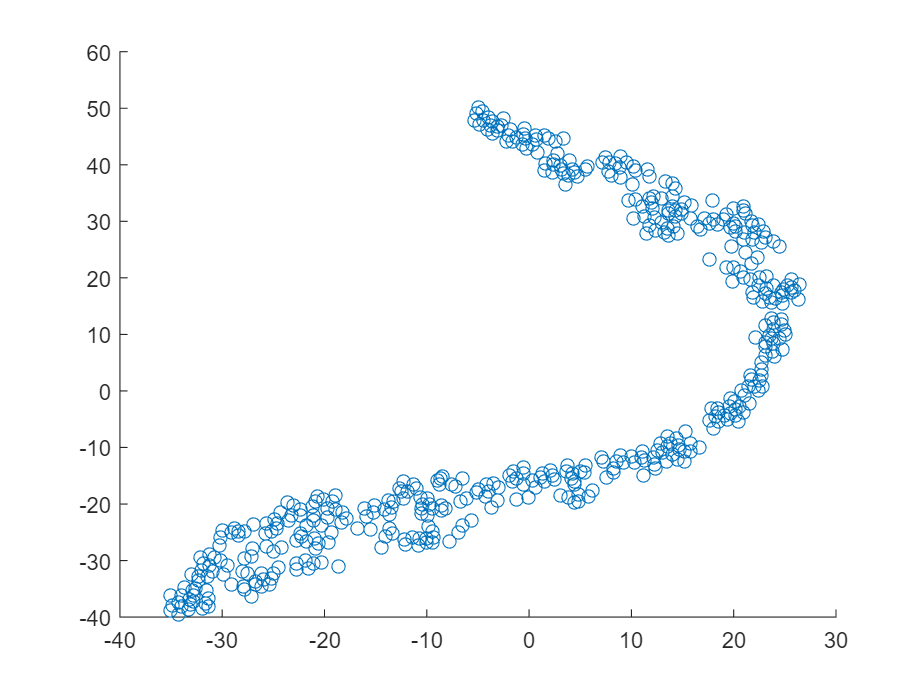

figure();
scatter(tsne_score(:,1), tsne_score(:,2))

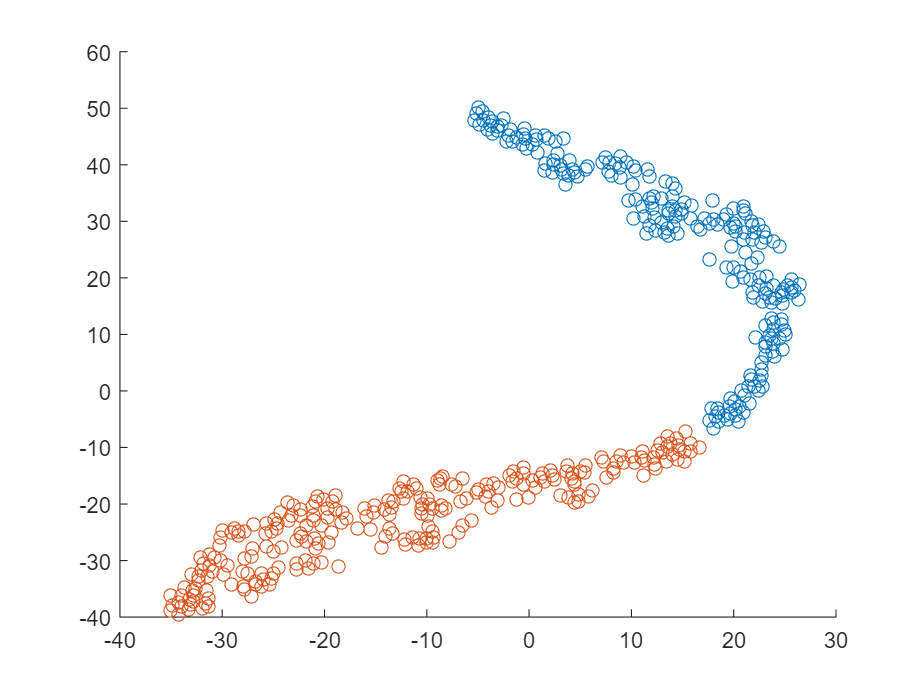


c = kmeans(tsne_score, 2);

figure(); hold on;
scatter(tsne_score(c==1,1), tsne_score(c==1,2))
scatter(tsne_score(c==2,1), tsne_score(c==2,2))